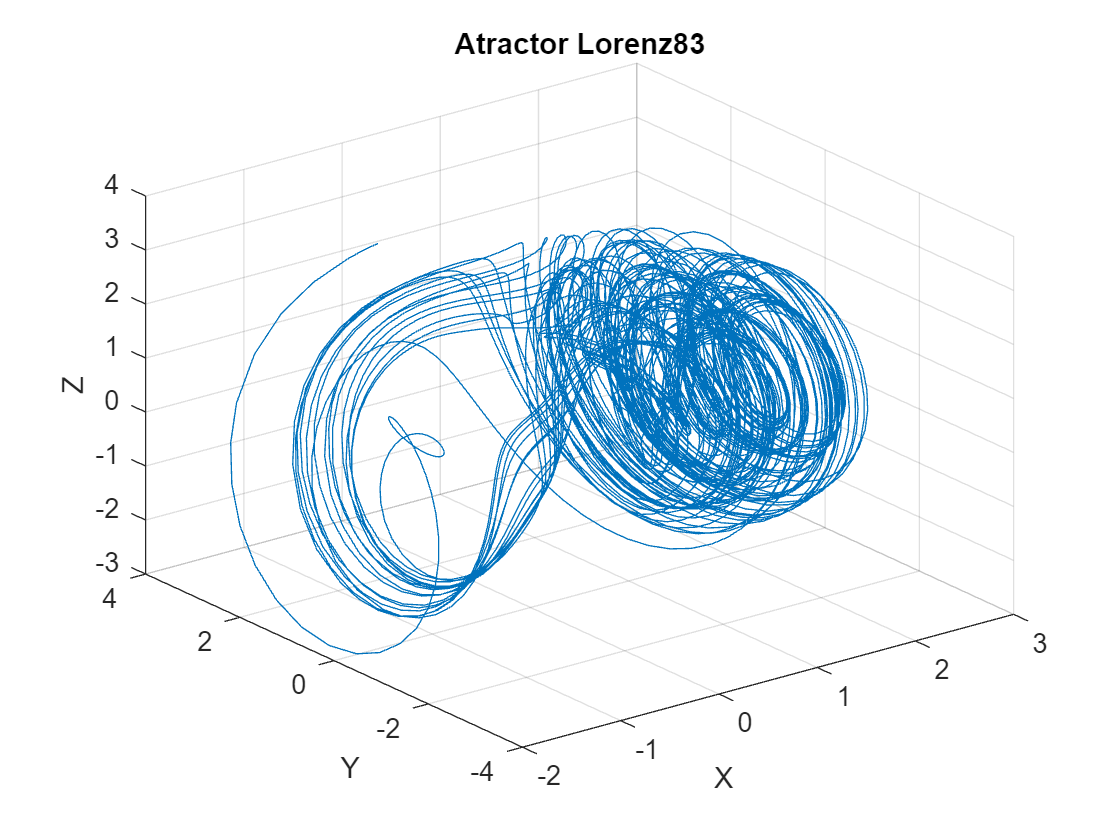

% Definir las constantes del sistema Lorenz83
A = 0.95;
B = 7.91;
F = 4.83;
G = 4.66;

% Definir la función de las ecuaciones diferenciales
lorenz83 = @(t, xyz) [
    -A * xyz(1) - xyz(2)^2 - xyz(3)^2 + A * F;
    -xyz(2) + xyz(1) * xyz(2) - B * xyz(1) * xyz(3) + G;
    -xyz(3) + B * xyz(1) * xyz(2) + xyz(1) * xyz(3)
];

% Condiciones iniciales
initial_conditions = [-0.2, 2.82, 2.71];

% Tiempo de integración
tspan = [0 100];

% Resolver el sistema de ecuaciones diferenciales
[t, xyz] = ode45(lorenz83, tspan, initial_conditions);

% Graficar la trayectoria en el espacio 3D
figure;
plot3(xyz(:,1), xyz(:,2), xyz(:,3));
xlabel('X');
ylabel('Y');
zlabel('Z');
title('Atractor Lorenz83');
grid on;